**Proyecto de MACHINE LEARNING**

En este proyecto clasificará las lombrices intestinales como vivas o muertas utilizando una red neuronal convolucional previamente entrenada.

- Cree un almacén de datos para las imágenes que están en la carpeta `WormImages`.

Como lo mencionado anteriormente se creo un datastore con el fin de crear un almacén de tatos llamado ds_lombrises.

ds_lombrises = imageDatastore('WormImages/*worm*.tif')

ds_lombrises =   ImageDatastore with properties:

                       Files: {
                              ' ...\Juan Esteban\Documents\MATLAB\prorecto 2\ProDL\WormImages\wormA01.tif';
                              ' ...\Juan Esteban\Documents\MATLAB\prorecto 2\ProDL\WormImages\wormA02.tif';
                              ' ...\Juan Esteban\Documents\MATLAB\prorecto 2\ProDL\WormImages\wormA03.tif'
                               ... and 90 more
                              }
                     Folders: {
                              'C:\Users\Juan Esteban\Documents\MATLAB\prorecto 2\ProDL\WormImages'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


- Obtenga las clasificaciones conocidas del archivo `WormData.csv `y utilícelas como etiquetas de imagen.

clasificacion=readcell('WormData.csv','Range','B2:C94');
clasificacion=categorical(clasificacion);
ds_lombrises.Labels=clasificacion;


-  Muestre las primeras 3 imágenes.

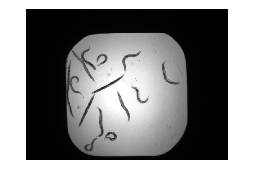

img1=readimage(ds_lombrises,1);
imshow(img1)

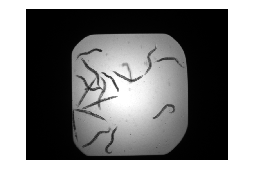

img2=readimage(ds_lombrises,2);
imshow(img2)

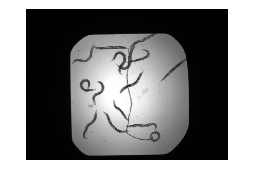

img3=readimage(ds_lombrises,3);
imshow(img3)

- Divida los datos en conjuntos de entrenamiento (60%) y prueba (40%).

[lombrises_entrena,lombrises_prueba]=splitEachLabel(ds_lombrises,0.6);

lombrises_entrena_au = augmentedImageDatastore([224 224 3],lombrises_entrena,...
                'ColorPreprocessing','gray2rgb')

'augmentedImageDatastore' requires Deep Learning Toolbox.

lombrises_prueba_au = augmentedImageDatastore([224 224 3],lombrises_prueba,...
                'ColorPreprocessing','gray2rgb')

- Cree almacenes de datos de imágenes aumentados para preprocesar las imágenes.

    ds_lombrises_au = augmentedImageDatastore([224 224 3],ds_lombrises,...
                'ColorPreprocessing','gray2rgb')
    

- Comience con la red previamente entrenada GoogleNet.

    
            
red_neu = googlenet;                % hacemos el llamado de la red
capas = red_neu.Layers;             % Extraemos las capas de la red
cap_entrada = red_neu.Layers(1)     % Estraemos la primer capa
tam_entrada = cap_entrada.InputSize;% Estraemos el tamaño de entrada de la red
cap_salida = red_neu.Layers(end);   % Capa de salida de la red    
categorias = cap_salida.Classes;    % Extraemos las clases de las salidas de la red
num_clases=numel(categorias(ds_lombris.Labels));


- Cree una nueva capa completamente conectada con 2 neuronas.

lgraph = layerGraph(red_neu)
newFc = fullyConnectedLayer(2,"Name","new_fc")

-  Sustituya la última capa totalmente conectada de la red con la nueva capa recién creada.

lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)


- Sustituya la capa final de la red con una nueva capa de clasificación.

newOut = classificationLayer("Name","new_out")
lgraph = replaceLayer(lgraph,"output",newOut)


- Cree una variable con las opciones predeterminadas del algoritmo de entrenamiento para el optimizador SGDM, excepto para la opción `InitialLearnRate`, que debe establecerse como `0.001`.

op_entrena= trainingOptions('sgdm','InitialLearnRate', 0.001);